## `Planteamiento de ecuaciones`

`Variables Simbolicas`

% Parametros del mecanismo
theta2_0 = sym("theta__2_0");
theta3_0 = sym("theta__3_0");
omega2 = sym("omega__2");
omega3 = sym("omega__3");
syms a b;

% Variable de tiempo
t = sym("t");

% Vector de incognitas q
R1x = sym("R__1_x");
R1y = sym("R__1_y");
theta1 = sym("theta__1");
R2x = sym("R__2_x");
R2y = sym("R__2_y");
theta2 = sym("theta__2");
R3x = sym("R__3_x");
R3y = sym("R__3_y");
theta3 = sym("theta__3");
q = [R1x, R1y, theta1, R2x, R2y, theta2, R3x, R3y, theta3]';
% Vector de velocidades
R1x_diff = sym("R__1_x_diff");
R1y_diff = sym("R__1_y_diff");
theta1_diff = sym("theta__1_diff");
R2x_diff = sym("R__2_x_diff");
R2y_diff = sym("R__2_y_diff");
theta2_diff = sym("theta__2_diff");
R3x_diff = sym("R__3_x_diff");
R3y_diff = sym("R__3_y_diff");
theta3_diff = sym("theta__3_diff");
q_diff = [R1x_diff, R1y_diff, theta1_diff, R2x_diff, R2y_diff, theta2_diff, R3x_diff, R3y_diff, theta3_diff]';

`Ecuaciones de Restricción y gobierno`

% Bancada:
e1 = R1x;
e2 = R1y;
e3 = theta1;
% Junta 1
e4 = R2x - ((a/2) * cos(theta2));
e5 = R2y - ((a/2) * sin(theta2));
% Junta 2
e6 = R2x + ((a/2) * cos(theta2)) - R3x + ((b/2) * cos(theta3));
e7 = R2y + ((a/2) * sin(theta2)) - R3y + ((b/2) * sin(theta3));
% Ecuaciones de Gobierno
e8 = theta2 - theta2_0 - (omega2*t);
e9 = theta3 - theta3_0 - (omega3*t);

`Matrices y Vectores de Calculo`

% Posición:
C = [e1, e2, e3, e4, e5, e6, e7, e8, e9]';  % Vector de ecuaciones de restricción
C_q = jacobian(C, q');                      % Jacobiana del vector C
% Velocidad:
C_t = diff(C,t);                            % Derivada temporal del vector C
% Aceleración
C_t_t = diff(C_t,t);                        % Derivada temporal de segundo orden del vector C
C_q_t = diff(C_q,t);                        % Derivada temporal de la matriz Jacobiana C_q
C_q_times_q_diff = jacobian(C_q*q_diff,q'); % Jacobiana del producto de C_q por el vector de velocidades
Qd = -(C_q_times_q_diff*q_diff) -(2*C_q_t*q_diff) -(C_t_t);

## `Implementación Computacional`

`Parámetros`

params_names = [a, theta2_0, omega2,...     % Eslabón 1
                b, theta3_0, omega3];       % Eslabón 2

params_values = [400, pi/3, pi/4,...        % Eslabon 1
                 300, pi/6, -pi/2 + pi/4];  % Eslabón 2

% Parámetros de simulación
max_iter = 10;                              % Numero de iteraciones
max_error = 1e-8;                           % Error admisible
steps = 100;                                % Numero de muestras
time = 1;                                   % Tiempo de simulación en segundos

`Remplazar parámetros en matrices simbolicas`

C = subs(C,params_names,params_values);
C_q = subs(C_q,params_names,params_values);
C_t = subs(C_t,params_names,params_values);
Qd = subs(Qd,params_names,params_values);

`Aplicación del método de Newton-Raphson`

% Numero de incógnitas
q_size = size(q,1);

% Variables de almacenamiento de resultados (cada fila corresponde a una iteración)
q_result = zeros(steps, q_size);
q_diff_result = zeros(steps, q_size);
q_diff2_result = zeros(steps, q_size);
time_vector = zeros(steps, 1);

% Valores iniciales:
q_values = [1, -4, 10, 90, 150, pi/4, 300, 400, pi/6]';
q_diff_values = zeros(q_size);

% Posición:    C_q(t,q)*deltaQ  = -C(t)           <- Newton-Raphson
% Velocidad:   C_q(t,q)*q_diff  = -C_t(t)         <- Sistema de ecuaciones lineales
% Aceleración: C_q(t,q)*q_diff2 = Qd(q, q_diff)   <- Sistema de ecuaciones lineales

for step=0:steps
    i = 0;
    current_error = 1;
    % Calculcular el tiempo de la iteracion
    iteration_time = (time/steps) * step;
    
    while (i<max_iter && current_error>max_error)

        % Calcular las matrices y vectores
        coefficients_matrix = double(subs(C_q,[q;t],[q_values;iteration_time]));
        constants_vector = double(subs(C,[q;t],[q_values;iteration_time]));

        % Calcular deltaq
        delta_q = linsolve(coefficients_matrix, -constants_vector);
        % Calcular nuevo q
        q_values = q_values + delta_q;

        % Calcular error máximo
        current_error = norm(constants_vector);
        i = i + 1;
    end

    % Calcular Velocidades
    constants_vector = double(subs(C_t,[q;t],[q_values;iteration_time]));
    q_diff_values = linsolve(coefficients_matrix, -constants_vector);

    % Calcular Aceleraciones
    constants_vector = double(subs(Qd,[q;q_diff;t],[q_values;q_diff_values;iteration_time]));
    q_diff2_values = linsolve(coefficients_matrix, constants_vector);

    % Guardar resultado de la iteración
    time_vector(step+1) = iteration_time;
    q_result(step+1,:) = q_values';
    q_diff_result(step+1,:) = q_diff_values';
    q_diff2_result(step+1,:) = q_diff2_values';
    % Print Time, Index, Error
    fprintf("Time: %d, Iteration: %i, Error: %d.\n", iteration_time, i, current_error);
end

Time: 0, Iteration: 3, Error: 1.006844e-14.
Time: 1.000000e-02, Iteration: 3, Error: 1.216084e-14.
Time: 2.000000e-02, Iteration: 3, Error: 3.092401e-14.
Time: 3.000000e-02, Iteration: 3, Error: 2.057884e-14.
Time: 4.000000e-02, Iteration: 3, Error: 3.912122e-14.
Time: 5.000000e-02, Iteration: 3, Error: 2.088689e-14.
Time: 6.000000e-02, Iteration: 3, Error: 3.566533e-14.
Time: 7.000000e-02, Iteration: 3, Error: 2.578394e-14.
Time: 8.000000e-02, Iteration: 3, Error: 1.471752e-14.
Time: 9.000000e-02, Iteration: 3, Error: 2.549678e-14.
Time: 1.000000e-01, Iteration: 3, Error: 1.993914e-14.
Time: 1.100000e-01, Iteration: 3, Error: 1.617454e-14.
Time: 1.200000e-01, Iteration: 3, Error: 1.532868e-14.
Time: 1.300000e-01, Iteration: 3, Error: 1.716726e-14.
Time: 1.400000e-01, Iteration: 3, Error: 1.265423e-14.
Time: 1.500000e-01, Iteration: 3, Error: 2.721782e-14.
Time: 1.600000e-01, Iteration: 3, Error: 2.655635e-14.
Time: 1.700000e-01, Iteration: 3, Error: 3.798813e-14.
Time: 1.800000e-01, I

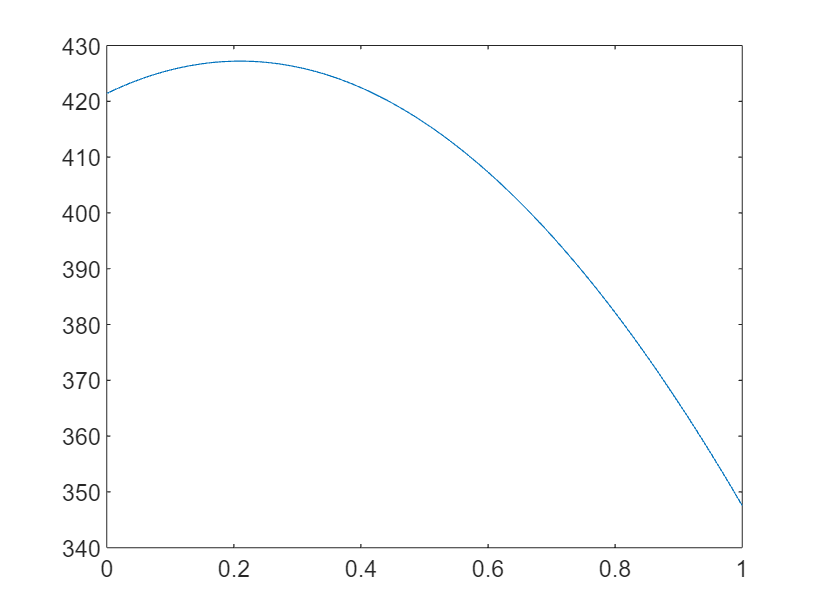

plot(time_vector, q_result(:,8))